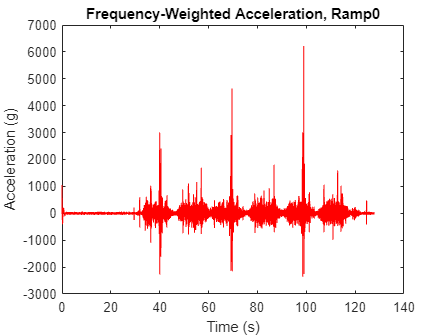

%Load Ramp data from csv
acceldata=readtable('Z_DispFrame_Ramp.csv'); 
accelDataRamp=fillmissing(acceldata, 'constant', 0); %Convert nan to 0
clear acceldata

%Trim white space
accelDataRamp.Properties.VariableNames = strtrim(accelDataRamp.Properties.VariableNames); 
%Check for duplicate data
assert(length(unique(accelDataRamp.Properties.VariableNames)) == length(accelDataRamp.Properties.VariableNames), 'Duplicate column names detected.');

%Extract time, acceleration data from CSV; define as separate variables
time = accelDataRamp.Time_Axis; %defines time vector (s)
%Raw Acceleration Data (g)
accRamp0 = accelDataRamp.Ramp_Test_0; %acceleration: Test Run Ramp0
accRamp01 = accelDataRamp.Ramp_Test_01; %acceleration: Test Run Ramp01
accRamp02 = accelDataRamp.Ramp_Test_02; %acceleration: Test Run Ramp02
accRamp03 = accelDataRamp.Ramp_Test_03; %acceleration: Test Run Ramp03

%Bandpass Filter Design - [1-80] Hz
%Define Bandpass Filter Variables
freqLo = 1; %Lower cutoff frequency (Hz)
freqHi = 80; %Upper cutoff frequency (Hz)
order = 4; %Filter Order
fs = 1024; %Sampling Frequency (Hz)
%Define Bandpass Filter
[b, a] = butter(order, [freqLo, freqHi]/(fs/2), 'bandpass');

%Apply the 1-80 Hz Bandpass filter to the acceleration data
%Bandpass filtered acceleration data (g)
FiltaccRamp0 = filter(b, a, accRamp0); 
FiltaccRamp01 = filter(b, a, accRamp01);
FiltaccRamp02 = filter(b, a, accRamp02);
FiltaccRamp03 = filter(b, a, accRamp03);

%Apply Wk frequency-weighted filter IAW ISO2631-1
%ISO 2631-1, Table 3 and Figure 2
%wf1=4; %Frequency band lower limit
%wf2=8; %Frequency Band Upper Limit
%f_center = sqrt(wf1*wf2) = 5.65 Hz; %Center Frequency (Hz)
Wk = 1046.579; %Interpolated Value for 5.65 Hz Center Frequency
%Apply Wk factor to bandpass filtered data
%Wk Frequency-Weighted, Bandpass Filtered Acceleration Data
WkFiltaccRamp0 = Wk * FiltaccRamp0;
WkFiltaccRamp01 = Wk * FiltaccRamp01; 
WkFiltaccRamp02 = Wk * FiltaccRamp02; 
WkFiltaccRamp03 = Wk * FiltaccRamp03; 

%Shift to Frequency Domain - Apply fft
fft_WkFiltaccRamp0 = fft(WkFiltaccRamp0);
fft_WkFiltaccRamp01 = fft(WkFiltaccRamp01);
fft_WkFiltaccRamp02 = fft(WkFiltaccRamp02);
fft_WkFiltaccRamp03 = fft(WkFiltaccRamp03);
%Define frequency vector
freqs = linspace (0, fs/2, length(WkFiltaccRamp01)/2 + 1);

%Create timetables for signal processing
%Create timetable with raw acceleration data
tempTableRaw_Ramp = table(seconds(time), accRamp0, accRamp01, accRamp02, accRamp03, 'VariableNames', {'Time', 'AccRamp0', 'AccRamp01', 'AccRamp02', 'AccRamp03'});
timetableRaw_Ramp = table2timetable(tempTableRaw_Ramp);

%Create timetable of bandpass filtered data
tempTableBPFilt_Ramp = table(seconds(time), FiltaccRamp0, FiltaccRamp01, FiltaccRamp02, FiltaccRamp03, 'VariableNames', {'Time', 'FiltAccRamp0', 'FiltAccRamp01', 'FiltAccRamp02', 'FiltAccRamp03'});
timetableBPFilt_Ramp = table2timetable(tempTableBPFilt_Ramp);

%Create timetable of Wk-filtered data
tempTableBPFiltWk_Ramp = table(seconds(time), WkFiltaccRamp0, WkFiltaccRamp01, WkFiltaccRamp02, WkFiltaccRamp03, 'VariableNames', {'Time', 'WkFiltaccRamp0', 'WkFiltaccRamp01', 'WkFiltaccRamp02', 'WkFiltaccRamp03'});
timetableBPFiltWk_Ramp = table2timetable(tempTableBPFiltWk_Ramp);
%Clear temptables
clear tempTableRaw_Ramp tempTableBPFilt_Ramp tempTableBPFiltWk_Ramp;

%Calculate running RMS
window_size_sec = 0.1 ; %Define window size (seconds)
windowSize = round(window_size_sec*fs);
%Calculate sqaured values
sq_WkFiltaccRamp01 = WkFiltaccRamp01.^2;
sq_WkFiltaccRamp02 = WkFiltaccRamp02.^2;
sq_WkFiltaccRamp03 = WkFiltaccRamp03.^2;
%Caclculate running RMS for each test run
rms_WkFiltaccRamp01 = sqrt(movmean(sq_WkFiltaccRamp01, windowSize));
rms_WkFiltaccRamp02 = sqrt(movmean(sq_WkFiltaccRamp02, windowSize));
rms_WkFiltaccRamp03 = sqrt(movmean(sq_WkFiltaccRamp03, windowSize));
%Create timetables for the running RMS values
timetableRMS_Ramp01 = timetable(seconds(time), rms_WkFiltaccRamp01, 'VariableNames', {'RMS_WkFiltaccRamp01'});
timetableRMS_Ramp02 = timetable(seconds(time), rms_WkFiltaccRamp02, 'VariableNames', {'RMS_WkFiltaccRamp02'});
timetableRMS_Ramp03 = timetable(seconds(time), rms_WkFiltaccRamp03, 'VariableNames', {'RMS_WkFiltaccRamp03'});
%Display the timetables if necessary
%disp(timetableRMS_Ramp01);
%disp(timetableRMS_Ramp02);
%disp(timetableRMS_Ramp03);
%disp(timetableRMS_Ramp04);
%Clear intermediate variables
clear sq_WkFiltaccRamp01 sq_WkFiltaccRamp02 sq_WkFiltaccRamp03;

%Define time, bandpass-filtered acceleration vectors for signal processing 
ta_Ramp0= [time FiltaccRamp0];
ta_Ramp01= [time FiltaccRamp01];
ta_Ramp02= [time FiltaccRamp02];
ta_Ramp03= [time FiltaccRamp03];

%Plot the desired signals
%Time-Domain Plots
figure;
plot(time, WkFiltaccRamp0, 'r');
title('Frequency-Weighted Acceleration, Ramp0');
xlabel ('Time (s)');
ylabel('Acceleration (g)');

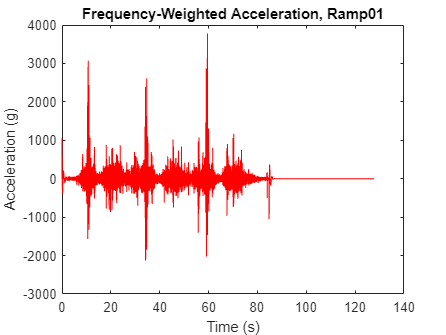


figure;
plot(time, WkFiltaccRamp01, 'r');
title('Frequency-Weighted Acceleration, Ramp01');
xlabel ('Time (s)');
ylabel('Acceleration (g)');

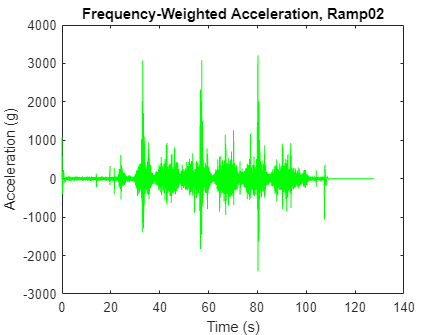


figure;
plot(time, WkFiltaccRamp02, 'g');
title('Frequency-Weighted Acceleration, Ramp02');
xlabel ('Time (s)');
ylabel('Acceleration (g)');

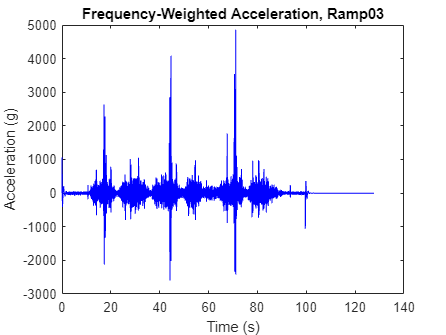


figure;
plot(time, WkFiltaccRamp03, 'b');
title('Frequency-Weighted Acceleration, Ramp03');
xlabel ('Time (s)');
ylabel('Acceleration (g)');

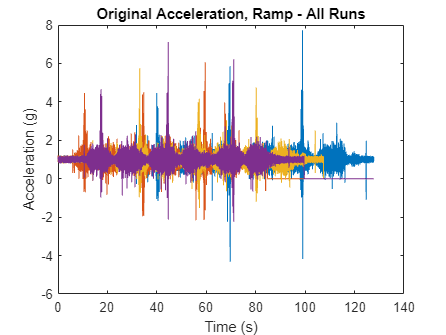


figure;
plot(time, accRamp0, time, accRamp01, time, accRamp02, time, accRamp03);
title('Original Acceleration, Ramp - All Runs');
xlabel ('Time (s)');
ylabel('Acceleration (g)');

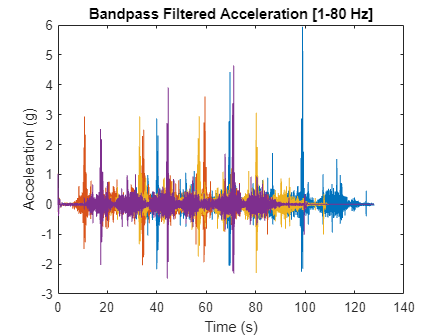


figure;
plot(time, FiltaccRamp0, time, FiltaccRamp01, time, FiltaccRamp02, time,FiltaccRamp03);
title('Bandpass Filtered Acceleration [1-80 Hz]');
xlabel ('Time (s)');
ylabel('Acceleration (g)');

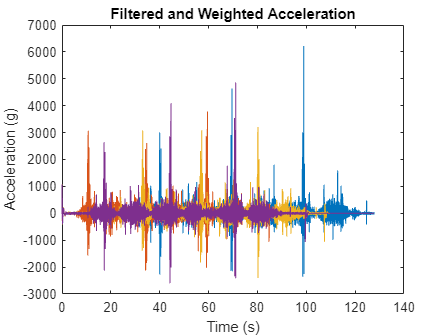


figure;
plot(time, WkFiltaccRamp0, time, WkFiltaccRamp01, time, WkFiltaccRamp02, time, WkFiltaccRamp03);
title('Filtered and Weighted Acceleration');
xlabel ('Time (s)');
ylabel('Acceleration (g)');

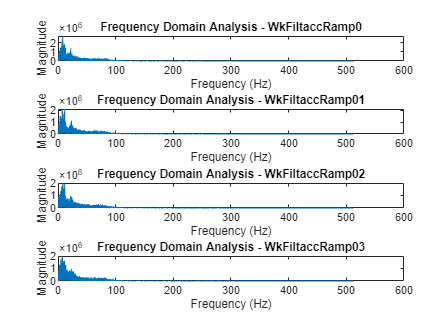


%Frequency Domain Plots
%Plot the magnitude spectrum
figure;
subplot(4,1,1);
plot(freqs, 2*abs(fft_WkFiltaccRamp0(1:length(freqs))));
title('Frequency Domain Analysis - WkFiltaccRamp0');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(4,1,2);
plot(freqs, 2*abs(fft_WkFiltaccRamp01(1:length(freqs))));
title('Frequency Domain Analysis - WkFiltaccRamp01');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(4,1,3);
plot(freqs, 2*abs(fft_WkFiltaccRamp02(1:length(freqs))));
title('Frequency Domain Analysis - WkFiltaccRamp02');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(4,1,4);
plot(freqs, 2*abs(fft_WkFiltaccRamp03(1:length(freqs))));
title('Frequency Domain Analysis - WkFiltaccRamp03');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

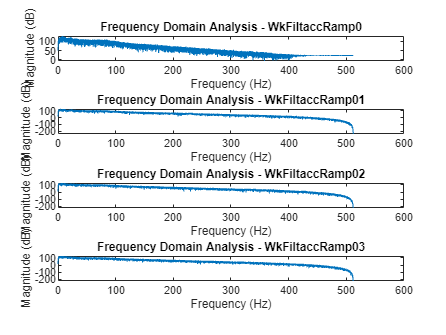


%Plot the magnitude spectrum as dB (logarithmic)
figure;
subplot(4,1,1);
plot(freqs, 20*log10(2*abs(fft_WkFiltaccRamp0(1:length(freqs)))));
title('Frequency Domain Analysis - WkFiltaccRamp0');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(4,1,2);
plot(freqs, 20*log10(2*abs(fft_WkFiltaccRamp01(1:length(freqs)))));
title('Frequency Domain Analysis - WkFiltaccRamp01');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(4,1,3);
plot(freqs, 20*log10(2*abs(fft_WkFiltaccRamp02(1:length(freqs)))));
title('Frequency Domain Analysis - WkFiltaccRamp02');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(4,1,4);
plot(freqs, 20*log10(2*abs(fft_WkFiltaccRamp03(1:length(freqs)))));
title('Frequency Domain Analysis - WkFiltaccRamp03');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');